% THis script only analysis Keith model continous photocurrent injection
% response with STA

% normalize x-axis

## Input

addpath('C:\Users\z5097900\OneDrive - UNSW\Desktop')                                            % this script require 'simpleSTC_hamed.m' & 'makeStimRow.m'

% % if input is response folder
% cd 'C:\Users\Mitch\OneDrive - UNSW\Desktop\wn_Responses\10Hz_27pA_25%_20s_1910\'
% cell = readmatrix ('ONGan.csv');                     
% stim_amp = readmatrix("WhiteNoiseAmps.csv",'NumHeaderLines',1);

% % if input is matlab.mat file
load 'C:\Users\z5097900\OneDrive - UNSW\Desktop\wn_Responses\25Hz_30pA_100%_5ms_co\5000\matlab.mat'
cell = oNgan;     
stim_amp = whiteNoiseAmps;

sample_per_ms = 10;

stim_frequency_Hz = 25;

pulse_dur_ms = 5;

thr_mA = -30;

thr_distance_sample = 30;

brust_thr_sample = 150;

nkt = 50;

## Preparing Stimulaiton Data

stim_amp = stim_amp(1 * stim_frequency_Hz + 1:end)                                              % cut first 1 sec 

stim_amp =    38.8000
   19.9000
   36.9000
   25.0000
   28.7000
   37.0000
   30.1000
   34.8000
   24.5000
   16.2000


## Spike Sorting + Sta

cell = cell(1000 * sample_per_ms +1 :end)                                                       % cut first 1 sec

cell =   -63.4713
  -63.4711
  -63.4710
  -63.4708
  -63.4706
  -63.4704
  -63.4703
  -63.4701
  -63.4699
  -63.4698



[spks_amp, spks_timing] = findpeaks(cell,'MINPEAKHEIGHT',thr_mA,'MINPEAKDISTANCE', thr_distance_sample)  

spks_amp =    23.5072
   23.5257
   23.5092
   25.5851
   16.8520
   20.7482
   22.5863
   22.4919
   24.4106
   18.3413


spks_timing =          333
        1130
        1952
        3216
        6330
        6409
        7116
        7526
        8746
        9194



bins = (1:((1000/stim_frequency_Hz)*sample_per_ms):length(cell))'

bins =            1
         401
         801
        1201
        1601
        2001
        2401
        2801
        3201
        3601



spks_count = histcounts(spks_timing, bins)'

spks_count =      1
     0
     1
     0
     1
     0
     0
     0
     1
     0



[sta, stc, mu, cov] = simpleSTC_hamed(stim_amp, spks_count, nkt);

## Burst Correction + Sta

% burst correction
spks_interval = diff(spks_timing);
burst_end = find(spks_interval > brust_thr_sample);
bc_spks_timing = [];

for i5 = 1:length(burst_end) - 1
    new_spks_times_holder = repmat(spks_timing(burst_end(i5) + 1), burst_end(i5 + 1) - burst_end(i5), 1);
    bc_spks_timing = vertcat(bc_spks_timing, new_spks_times_holder);
end

bc_spks_count = histcounts(bc_spks_timing, bins)';

[bc_sta, bc_stc, bc_mu, bc_cov] = simpleSTC_hamed(stim_amp, bc_spks_count, nkt);

## Stimulation + Recording Ploting

% stimulation ploting
stim_duration_sample = pulse_dur_ms*sample_per_ms; 
pulse = repmat(stim_amp, 1, stim_duration_sample)';
inter_pulse = zeros((1000/stim_frequency_Hz)*sample_per_ms-pulse_dur_ms*sample_per_ms, length(stim_amp));
%init = zeros(700,1)
stim_wav = [pulse;inter_pulse];    
plot(stim_wav(:));
hold on
ylabel('Photocurrent injection amplitude (pA)')
xlabel('Time (0.1 ms)')
title('Light stimulation')

% recording ploting
% plot(cell);
% 

cone = cone(1000 * sample_per_ms +1 :end)   

cone =   -42.4816
  -42.6077
  -42.7306
  -42.8502
  -42.9667
  -43.0802
  -43.1907
  -43.2983
  -43.4032
  -43.5053


plot((cone + 50)*50);

a2 = a2(1000 * sample_per_ms +1 :end)   

a2 =   -43.4925
  -43.4921
  -43.4918
  -43.4914
  -43.4911
  -43.4907
  -43.4904
  -43.4900
  -43.4897
  -43.4894


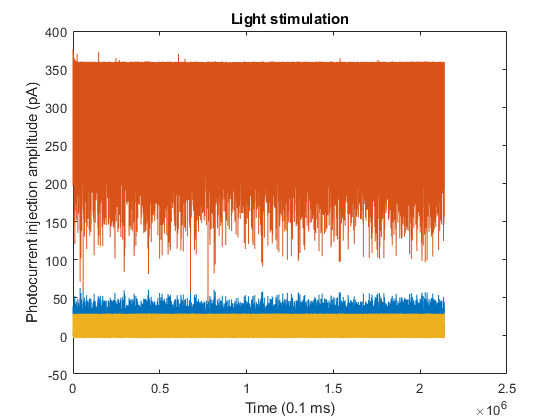

plot((a2 + 50));

% plot (bc_spks_timing,cell(bc_spks_timing),'*') ;
% plot(spks_timing,cell(spks_timing),'o') ;
hold off

## Sta Ploting

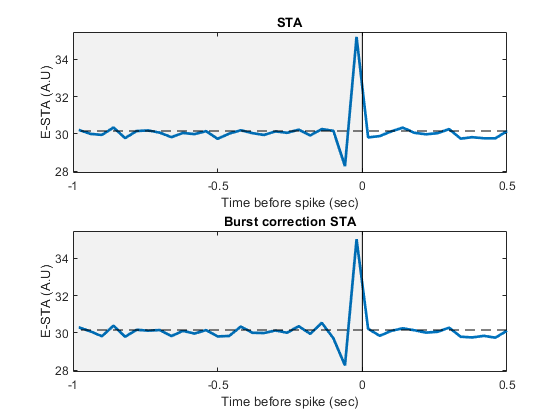

tvec = (-nkt/2+1:nkt/2)'*1/stim_frequency_Hz-.5/stim_frequency_Hz;                                    % vector of time indices (in units of stim frames)

subplot(2,1,1)
plot(tvec, sta,'LineWidth',2);
hold on
patch([-2 0 0 -2],[1200 1200 0  0],'black')
alpha .05;
line([tvec(1),tvec(end)],[mean(stim_amp) ,[mean(stim_amp)]],'Color','k','LineStyle','--');
line([tvec(nkt/2)+.5/stim_frequency_Hz tvec(nkt/2)+.5/stim_frequency_Hz], [-1200 0],'Color','k','LineStyle','--');

title('STA');
xlabel('Time before spike (sec)'); 
ylabel('E-STA (A.U)');
ylim([min(bc_sta)-min(bc_sta)/80,max(bc_sta)+max(bc_sta)/80]);                 
xlim([-1,.5]);
hold off

subplot(2,1,2)
p2 = plot(tvec, bc_sta,'LineWidth',2);
hold on
patch([-2 0 0 -2],[1200 1200 0  0],'black')
alpha .05;
line([tvec(1),tvec(end)],[mean(stim_amp) ,[mean(stim_amp)]],'Color','k','LineStyle','--');
line([tvec(nkt/2)+.5/stim_frequency_Hz tvec(nkt/2)+.5/stim_frequency_Hz], [-1200 0],'Color','k','LineStyle','--');

title('Burst correction STA');
xlabel('Time before spike (sec)'); 
ylabel('E-STA (A.U)');
ylim([min(bc_sta)-min(bc_sta)/80,max(bc_sta)+max(bc_sta)/80]);                 
xlim([-1,.5]);
hold off